# Tina Höflich (7314712), Christian  Lange (2463229)

## Fahrzeugdaten laden

FzgDaten;

FzgDaten geladen


## 9.1 Längsdynamik

### 9.1.1 Simulation Bremsvorgang

setzen der Daten entsprechend der Daten auf Abbildung 1.23 im Skript

ax_1 = -1;
ax_2 = -9;
T0 =0.8;
T1 =0.2;
T2 = 0.2;

Bremsvorgang simulieren mit vorherigen Daten als Input

model = 'Bremsvorgang';
load_system(model)

simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
repeating_sequence = [0 T0 T0+T1 T0+T1+T2 20];
repeating_sequence_out = [0 0 ax_1 ax_2 ax_2];

Daten aus dem Simulink-Modell auslesen

out = sim(simIn);
outputs = out.yout;
t = out.tout;
s = outputs{1}.Values.Data;
v = outputs{2}.Values.Data;
a = outputs{3}.Values.Data;

X und Y-Werte für $T_0, T_1$ und $T_2$ setzen:

x_line_points_T0 = [T0 T0];
y_line_points_T0 = [-1 0];

x_line_points_T1 = [T0+T1 T0+T1];
y_line_points_T1 = [-1 -ax_1];

x_line_points_T2 = [T0+T1+T2 T0+T1+T2];
y_line_points_T2 = [-1 -ax_2];


Beschleunigung darstellen nach Abbildung 1.25:

#### Verlauf von Fahrzeugverzögerung, Fahrgeschwindigkeit und Fahrweg über der Zeit während eines Bremsvorgangs

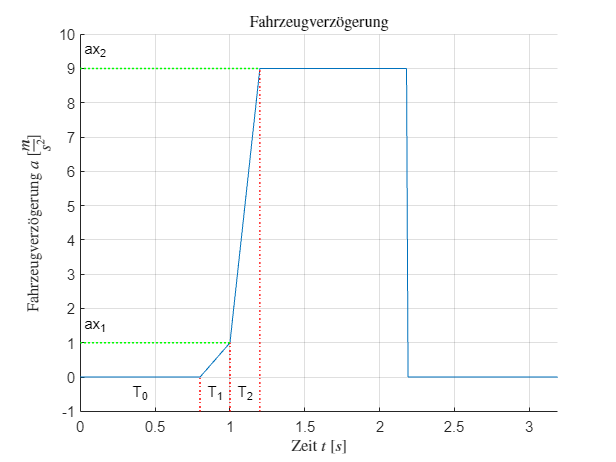

figure;
hold on;
plot(t,-a)

%Anzeige der Zeitintervalle
plot(x_line_points_T0, y_line_points_T0, 'r:', 'LineWidth', 1);
text(T0*0.5, -0.5, 'T_0', 'HorizontalAlignment', 'center');
plot(x_line_points_T1, y_line_points_T1, 'r:', 'LineWidth', 1);
text(T0+T1*0.5, -0.5, 'T_1', 'HorizontalAlignment', 'center');
plot(x_line_points_T2, y_line_points_T2, 'r:', 'LineWidth', 1);
text(T0+T1+T2*0.5, -0.5, 'T_2', 'HorizontalAlignment', 'center');

%Anzeigen der verschiedenen Bremsbeschleunigungen
x_line_points_ax1 = [0 T0+T1];
y_line_points_ax1 = [-ax_1 -ax_1];
plot(x_line_points_ax1, y_line_points_ax1, 'g:', 'LineWidth', 1);
text(0.1, -ax_1+0.5, 'ax_1', 'HorizontalAlignment', 'center');

x_line_points_ax2 = [0 T0+T1+T2];
y_line_points_ax2 = [-ax_2 -ax_2];
plot(x_line_points_ax2, y_line_points_ax2, 'g:', 'LineWidth', 1);
text(0.1, -ax_2+0.5, 'ax_2', 'HorizontalAlignment', 'center');

xlabel("Zeit $t$ $[s]$", 'Interpreter','latex')
ylabel('Fahrzeugverz\"ogerung $a$ $[\frac{m}{s^2}]$','Interpreter','latex')
title ('Fahrzeugverz\"ogerung', 'Interpreter','latex');
ylim([-1, max(-a)+1])
xlim([min(t), max(t)])

hold off;
grid on

Geschwindigkeit über die Zeit darstellen nach Abbildung 1.25

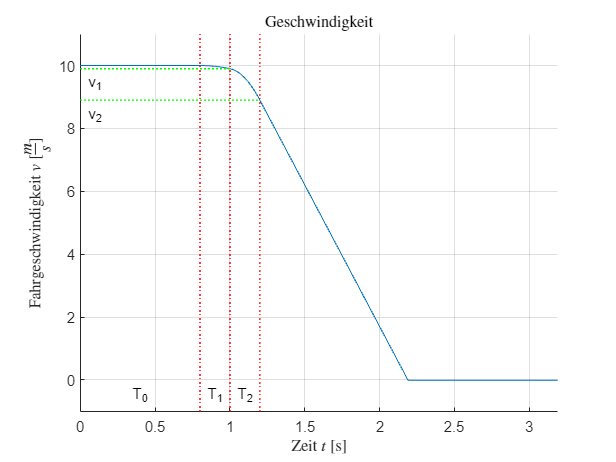

figure;
hold on;
plot(t,v)

%Anzeige der Zeitintervalle
plot(x_line_points_T0, [-1 max(v)+1], 'r:', 'LineWidth', 1);
text(T0*0.5, -0.5, 'T_0', 'HorizontalAlignment', 'center');
plot(x_line_points_T1, [-1 max(v)+1], 'r:', 'LineWidth', 1);
text(T0+T1*0.5, -0.5, 'T_1', 'HorizontalAlignment', 'center');
plot(x_line_points_T2, [-1 max(v)+1], 'r:', 'LineWidth', 1);
text(T0+T1+T2*0.5, -0.5, 'T_2', 'HorizontalAlignment', 'center');

%Anzeigen der Geschwindigkeiten
%v1
index_v1 = t == T0+T1;
v1 = v(index_v1);
plot([0 T0+T1], [v1 v1], 'g:', 'LineWidth', 1);
text(0.1, v1-0.5, 'v_1', 'HorizontalAlignment', 'center');

%v2
index_v2 = t == T0+T1+T2;
v2 = v(index_v2);
plot([0 T0+T1+T2], [v2 v2], 'g:', 'LineWidth', 1);
text(0.1, v2-0.5, 'v_2', 'HorizontalAlignment', 'center');

xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Fahrgeschwindigkeit $v$ $[\frac{m}{s}]$", 'Interpreter','latex')
title ('Geschwindigkeit', 'Interpreter','latex');
ylim([-1, max(v)+1])
xlim([min(t), max(t)])

hold off;
grid on

Strecke über die Zeitdarstellen nach Abbildung 1.25

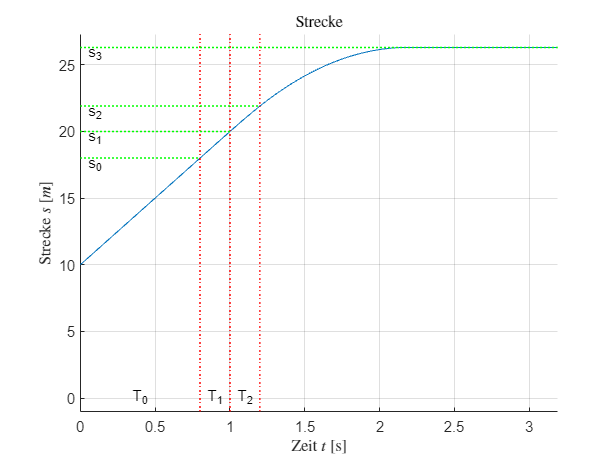

figure;
hold on;
plot(t,s)

%Anzeige der Zeitintervalle
plot(x_line_points_T0, [-1 max(s)+1], 'r:', 'LineWidth', 1);
text(T0*0.5, 0, 'T_0', 'HorizontalAlignment', 'center');
plot(x_line_points_T1, [-1 max(s)+1], 'r:', 'LineWidth', 1);
text(T0+T1*0.5, 0, 'T_1', 'HorizontalAlignment', 'center');
plot(x_line_points_T2, [-1 max(s)+1], 'r:', 'LineWidth', 1);
text(T0+T1+T2*0.5, 0, 'T_2', 'HorizontalAlignment', 'center');

%Anzeigen der Strecken
%s0
index_s0 = t == T0;
s0 = s(index_s0);
plot([0 T0], [s0 s0], 'g:', 'LineWidth', 1);
text(0.1, s0-0.5, 's_0', 'HorizontalAlignment', 'center');

%s1
index_s1 = t == T0+T1;
s1 = s(index_s1);
plot([0 T0+T1], [s1 s1], 'g:', 'LineWidth', 1);
text(0.1, s1-0.5, 's_1', 'HorizontalAlignment', 'center');

%s2
index_s2 = t == T0+T1+T2;
s2 = s(index_s2);
plot([0 T0+T1+T2], [s2 s2], 'g:', 'LineWidth', 1);
text(0.1, s2-0.5, 's_2', 'HorizontalAlignment', 'center');

%s3
plot([0 max(t)], [max(s) max(s)], 'g:', 'LineWidth', 1);
text(0.1, max(s)-0.5, 's_3', 'HorizontalAlignment', 'center');

xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Strecke $s$ $[m]$", 'Interpreter','latex')
title ('Strecke', 'Interpreter','latex');
ylim([-1, max(s)+1])
xlim([min(t), max(t)])

hold off;
grid on

### 9.1.2 Tangentialkraftdiagramm

Für die Berechnung der Tangentialkraftverteilung werden die Parameter $\chi$ und $\psi$mit folgenden Formlen berechnet:

$\chi = \frac{h_s}{l}$ und $\psi = \frac{l_v}{l}$

clf;

psi = Lv / L;
chi = hs / L;

Für die ideale Bremskraftverteilung gilt:

$\frac{F_{Bv}}{G_g} = z*(1-\psi + z * \chi)$ mit $-\frac{1-\psi}{\chi} \leq z \leq 0$ und 

$\frac{F_{Bh}}{G_g} = z*(\psi + z * \chi)$ mit $0 \leq z \leq \frac{\psi}{\chi}$

z = linspace(-(1-psi)/chi,psi/chi);
FBv_gg = z .* (1 - psi + z * chi);
FBh_gg = z .* (psi - chi * z);

Darstellung der Kurve der idealen Bremskraftverteilung:

figure
hold on
plot(FBv_gg, FBh_gg)

Darstellung der Linien konstanter Abbremsung als  Maß für die bei alleiniger Blockierung der Vorderachse erreichte Fahrzeugverzögerung:

for z = 0:0.2:1.2
    x = linspace(0, z);
    y = -1 * x + z;
    plot(x, y, 'b')
end

text(0.52, 0.95, 'Linien konstanter Abbremsung', 'Color', 'b');
line([0.38, 0.5], [0.83, 0.95], 'Color', 'b')
line([0.38, 0.5], [0.83, 0.95], 'Color', 'b')
text(0.5, 0.8, '$z=1.2$', 'Rotation', -45, 'Interpreter', 'latex')
text(0.4, 0.7, '$z=1.0$', 'Rotation', -45, 'Interpreter', 'latex')
text(0.3, 0.6, '$z=0.8$', 'Rotation', -45, 'Interpreter', 'latex')


Darstellung der Linien konstanter Reibungszahlen:

Ay = -(1-psi)/chi;
Bx = psi/chi;

for my = 0.6:0.4:1.0
    z = my;
    x = my * (1-psi + z * chi);
    y = my * (psi - z * chi);

    zv = my * psi / (1 + my * chi);
    zh = my * (1-psi) / (1 - my * chi);
    
    plot([0 x], [Ay, y], 'k-')
    plot([0 Bx], [zv, 0], 'k-')

    % plot([0 zh], [Ay, 0], 'r-')
end

text(1.3, 0.26, '$\mu_h=1.0$', 'Rotation', -10, 'Interpreter', 'latex')
text(1.3, 0.1, '$\mu_h=0.6$', 'Rotation', -7, 'Interpreter', 'latex')

text(0.36, -1,0, '$\mu_v=1.0$', 'Rotation', 75, 'Interpreter', 'latex')
text(0.17, -1.0, '$\mu_v=0.6$', 'Rotation', 80, 'Interpreter', 'latex')

text(1.32, -0.7, 'Linien konstanter Reibungszahlen', 'Color', 'k');
line([0.58, 1.32], [-0.4, -0.65], 'Color', 'k')
line([1.8, 1.35], [0.08, -0.65], 'Color', 'k')

 Darstellung der Linie einer installierten Festabstimmung:

steigung = y / x;
plot([0, 1.2], [0, steigung*1.2], 'k')

text(1.22, steigung*1.2, 'Linie einer installierten Festabstimmung', 'Color', 'k');

Darstellung der Punkte $D$, $E$, und $C$:

Punkt $D$ und $E$ sind die Punkte, in denen  die Linien konstanter Reibungszahlen  die Koordinatenachsen schneiden in den sogenannten Ausfallpunkten 

plot(zh, 0, 'k.', 'MarkerSize', 14)
text(zh+0.05, 0.05, 'D', 'Color', 'k');

plot(0, zv, 'k.', 'MarkerSize', 14)
text(-0.09, zv+0.05, 'E', 'Color', 'k');

plot(x, y, 'k.', 'MarkerSize', 14)
text(x+0.07, y+0.07, 'C', 'Color', 'k');

Die Parabel kreuzt die Koordinatenachsen an den Punkten, die einer Beschleunigung oder Verzögerung entsprechen, bei der die Hinter- oder Vorderachse gerade den Boden verlässt. An diesen Punkten wird die Tangentialkraft an der abhebenden Achse null, unabhängig vom Reibungskoeffizienten. Daher repräsentieren die Schnittpunkte A und B, an denen die Parabel die Achsen schneidet, die geometrischen Positionen aller möglichen Reibungszahlen.

Darstellung der Punkte $A(0, -\frac{1-\psi}{\chi})$ und $B(\frac{\psi}{\chi}, 0)$:

plot(0, Ay, 'k.', 'MarkerSize', 14)
text(0.1, Ay, 'A', 'Color', 'k');
plot(Bx, 0, 'k.', 'MarkerSize', 14)
text(Bx, 0.1, 'B', 'Color', 'k');

Anpassen des Diagramms:

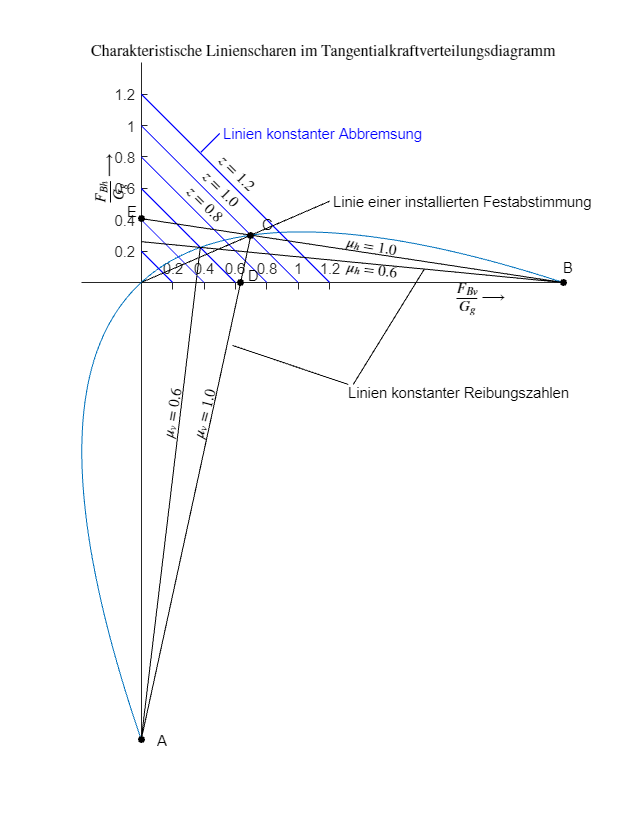

axis equal
ylim([Ay, 1.4])
xlim([-inf, Bx])
xticks(0.2:0.2:1.2);
yticks(0.2:0.2:1.2);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

text(2, -0.1, "$\frac{F_{Bv}}{G_g} \longrightarrow$", "Interpreter", "latex");
text(-0.2, 0.5, "$\frac{F_{Bh}}{G_g} \longrightarrow$", "rotation", 90, "Interpreter", "latex");
title("Charakteristische Linienscharen im Tangentialkraftverteilungsdiagramm", 'Interpreter','latex')

% Größe anpassen
pos = get(gcf, 'position');
pos(4) = 1000;
pos(3) = pos(4) * 3 / 4;
set(gcf, 'position', pos);
hold off

## 9.2 Querdynamik

### 9.2.1 Lineare Übertragungsfunktion

Ch_stern  = Ch / Fnh;
Cv_stern = Cv / Fnv;

Berechnung des Eigenlenkgradient EG

EG = (1/g) * (1/Cv_stern - 1/ Ch_stern);

Berechnung des Schwimmwinkelgradient SG

SG = 1 / (g * Ch_stern);

Umrechnung in m/s

v = 60 / 3.6;

Berechnung der Zählerzeitkonstante $T_z$

Tz = v * SG;

Überprüfung des Wertes der Zählerzeitkonstante $T_z$ mit den anderen Formeln:

Tz_1 = Tz;
Tz_2 = (m * v *Lv) / (Ch * L);
Tz_3 = v / (Ch_stern * g);
tolerance = 10^-13;

if abs(Tz_3-Tz_2) < tolerance && abs(Tz_1-Tz_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", Tz_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 0.082667

Berechnung der Abklingkonstante  $2\sigma$ und $\sigma$

abklingkonstante = (m * (Cv * Lv^2 + Ch * Lh^2) + J * (Cv + Ch)) / (J * m * v);

Überprüfung des Wertes der Abklingkonstante $2 \sigma$ mit den anderen Formeln :

zwei_sigma_1 = abklingkonstante;
zwei_sigma_2 = (m * Lv * Lh * (EG * Lh + SG * L) + J * (EG * Lv + SG * L)) / (J * SG * L * v * (EG + SG));
zwei_sigma_3 = g * (m * Lv * Lh * (Cv_stern * Lv + Ch_stern * Lh) + J * (Cv_stern * Lh + Ch_stern * Lv)) / (J * L *v);
if abs(zwei_sigma_3-zwei_sigma_2) < tolerance && abs(zwei_sigma_1-zwei_sigma_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", zwei_sigma_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 18.426797

sigma = zwei_sigma_1 / 2;

Berechnung der ungedämpfte Eigenfrequenz $\omega^2_0$

Eigenfrequenz = (m*v^2*(Ch * Lh - Cv * Lv) + Cv * Ch * L^2)/ (J  * m * v^2);
omega_0 = sqrt(Eigenfrequenz);

Überprüfung des Wertes der ungedämpfte Eigenfrequenz $\omega^2_0$ mit den anderen Formeln:

omega_0_quadrat_1 = Eigenfrequenz;
omega_0_quadrat_2 = (m * Lv * Lh) / (SG * J * L *v^2) * (L + EG * v^2)/(EG + SG);
omega_0_quadrat_3 = (m * g * Lv * Lh) / (J * L * v^2) * (v^2 * (Ch_stern - Cv_stern) + g * L * Cv_stern * Ch_stern);

tolerance = 10^-13;
if abs(omega_0_quadrat_3-omega_0_quadrat_2) < tolerance && abs(omega_0_quadrat_1-omega_0_quadrat_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", omega_0_quadrat_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 115.161290

Berechnung der stationäre Gierverstärkung $\frac{K}{\omega^2_0}$

gierverstaerkung = (Cv * Ch * L) / (J * m * v * Eigenfrequenz);

Überprüfung des Wertes der Stationären Gierverstärkung $\frac{K}{\omega^2_0}$ mit den anderen Formeln :

K_omega_0_quadrat_1 =  gierverstaerkung;
K_omega_0_quadrat_2 = v / (L + EG * v^2);
K_omega_0_quadrat_3 = (Cv_stern * Ch_stern * g^2 * Lv * Lh * m)/(J * L * v * omega_0_quadrat_1);
if abs(K_omega_0_quadrat_3-K_omega_0_quadrat_2) < tolerance && abs(K_omega_0_quadrat_1-K_omega_0_quadrat_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", K_omega_0_quadrat_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 3.781513

Berechnung des Dämpfungsmaß

daempfungsmass = sigma / omega_0;

Variablen output

fprintf("Der Eigenlenkgradient beträgt: %f\n" + ...
    "Der Schwimmwinkelgradient beträgt: %f\n" +...
    "Die Zählerzeitkonstante beträgt %f\n" +...
    "Die Gierverstärkung beträgt %f\n" +...
    "Die Abklingkonstante = 2sigma beträgt %f\n" +...
    "Der Dämpfungsmaß beträgt: %f", EG, SG, Tz, gierverstaerkung, abklingkonstante, daempfungsmass);

Der Eigenlenkgradient beträgt: 0.005787
Der Schwimmwinkelgradient beträgt: 0.004960
Die Zählerzeitkonstante beträgt 0.082667
Die Gierverstärkung beträgt 3.781513
Die Abklingkonstante = 2sigma beträgt 18.426797
Der Dämpfungsmaß beträgt: 0.858552

#### Plot über die Geschwindigkeit

Hierfür werden die Formeln $K$/$\omega_0^2$ , $2\sigma$, $\sigma$, $\omega_0^2$, $\omega_0$ und $D$ in Abhängigkeit von der Geschwindigkeit $v$ neu berechnet:


v_kmh = linspace(0,250,251);
v = v_kmh ./ 3.6;
Tz_v = v .* SG;
abklingkonstante_v = (m * (Cv * Lv * Lv + Ch * Lh.^2) + J * (Cv + Ch)) ./ (J * m * v); 
sigma_v = abklingkonstante_v / 2;
Eigenfrequenz_v = (m .* v.^2 *(Ch * Lh - Cv * Lv) + Cv * Ch * L^2) ./ (J  * m .* v.^2);
gierverstaerkung = (Cv * Ch * L) ./ ( J .* m .* v .* Eigenfrequenz_v); % K/w_0^2)
omega_0 = sqrt(Eigenfrequenz_v);
daempfungsmass = sigma_v ./ omega_0;

Berechnung der ungedämpften Eigenfrequenz $\nu_0$ mit fortlaufender Geschwindigkeit

v_0 = omega_0 / (2 * pi); % ni0

Berechnung der gedämpften Eigenfrequenz $\nu$ mit fortlaufender Geschwindigkeit

v_g = v_0 .* sqrt(1-(daempfungsmass.^2)); %ni_ret

#### Plot der ungedämpften Eigenfrequenz über die Geschwindigkeit

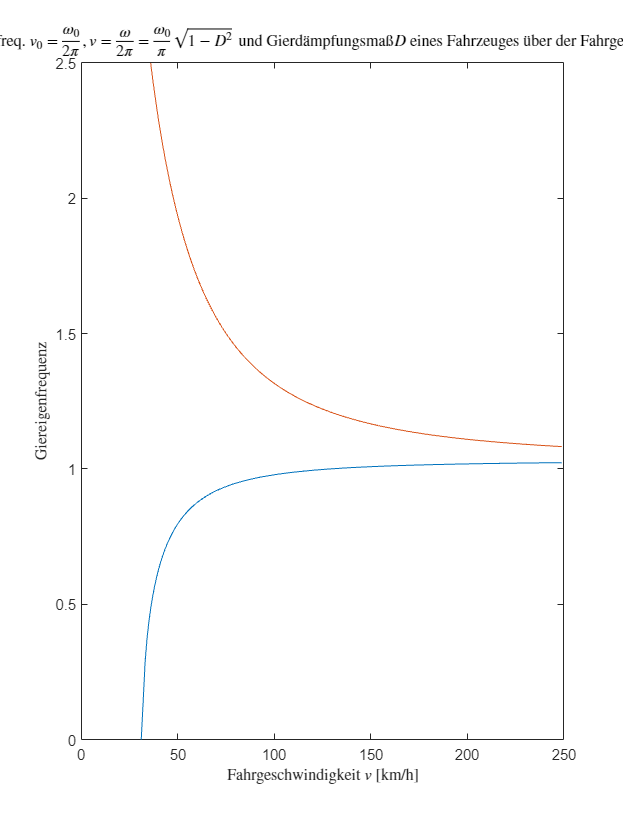

xindex = find(real(v_g) > 0);

plot(real(v_kmh(xindex-1:250)), real(v_g(xindex-1:250)));
hold on 
plot(real(v_kmh(xindex-1:250)), real(v_0(xindex-1:250))) ;
xlim([0 250]); 
ylim([0 2.5]); 
ylabel("Giereigenfrequenz", "Interpreter", "latex") 
xlabel("Fahrgeschwindigkeit $v$ [km/h]", "Interpreter", "latex") 
title (['Giereigenfreq. $v_0 = \frac{\omega_0}{2\pi}, v = \frac{\omega}{2\pi} = \frac{\omega_0}{\pi}\sqrt{1-D^2}$' ... 
    ' und Gierd\"ampfungsma\ss $D$ eines Fahrzeuges \"uber der Fahrgeschwindigkeit'] , 'Interpreter','latex') 
hold off 

#### Plot des Gierdämpfungsmaß über die Geschwindigkeit:

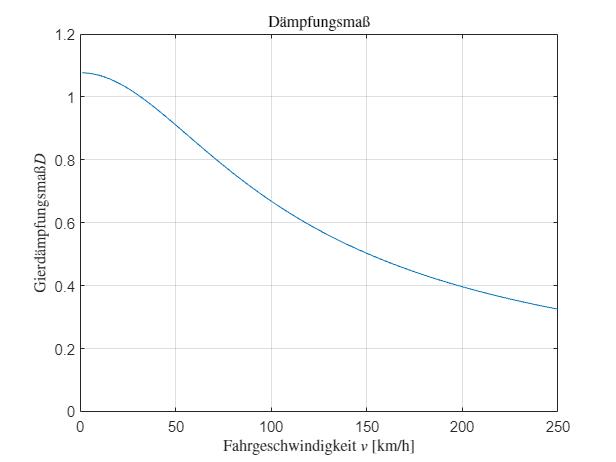

figure
plot(v_kmh, daempfungsmass)
xlim([0 250]);
title('D\"ampfungsma\ss', 'Interpreter','latex') ;

xlabel("Fahrgeschwindigkeit $v$ [km/h]", "Interpreter", "latex");
ylabel('Gierd\"ampfungsma\ss $D$', "Interpreter", "latex");
ylim([0 1.2]);
grid

### 9.2.2 Lenkradwinkelsprung  

#### Sprungantwort: von G(s)= 𝜓(𝑠)/ 𝛿(𝑠) 

unter Verwendung der Parameter

Berechnung von $G(s) = \frac{\dot{\psi}(s)}{\delta(s)} = K \cdot \frac{1 + T_zs}{s^2+2\sigma s + \omega_0^2}$

v = 60 / 3.6;
Tz = v * SG;
K = (Ch * Cv * L) / (J * m * v);

tf_gs = tf([ K*Tz K ] , [1  abklingkonstante Eigenfrequenz]);

Visaualisierung des Bode Diagramm von G(S)

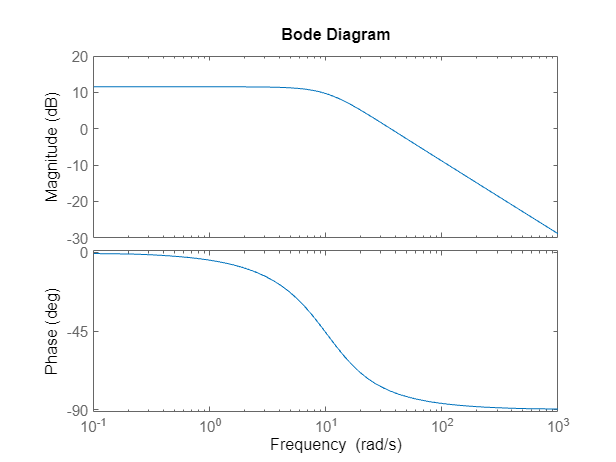

bode(tf_gs)

Berechnung der Sprungantwort :

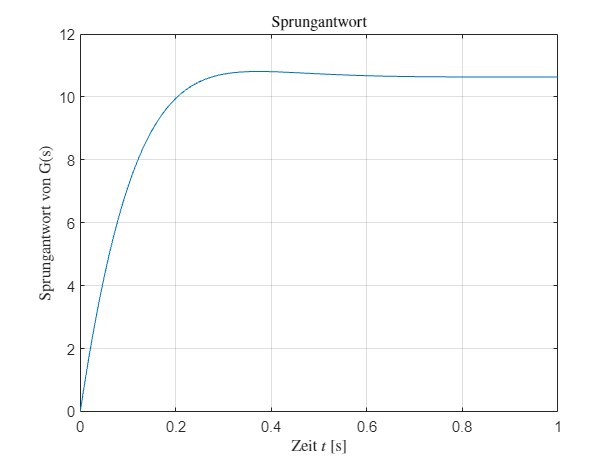

config = RespConfig('Amplitude', 45/iS);
[y_out, t_out] = step(tf_gs, 1.0, config);
figure; % Create a new figure
plot(t_out, y_out); % Plot the step response
title('Sprungantwort', 'Interpreter','latex') ;
xlabel("Zeit $t$ [s]", "Interpreter", "latex");
ylabel(" Sprungantwort von G(s)", "Interpreter", "latex");

% Show grid
grid on;

#### Nichtlineares Einspurmodell  

model = 'Lenkradwinkelsprung';
load_system(model)
simIn = Simulink.SimulationInput(model);

*Hinweis: Alle Modellparameter, die mit *setModelParameter() *gesetzt werden können, lassen sich folgendermaßen ermitteln:*

Konfiguration der Simulation: $t_\text{Start}=0$, $t_\text{Stop}=t_{\rm end}$, Integration mit fester Zeitschrittweite $\Delta t=0.01$  

tend = 1;
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01',...
    'StartTime','0',...
    'StopTime',num2str(tend));

Konfiguration des Lenkradwinkelsprungs mit $\delta_\text{H}=45\degree $ und $v=60\text{ km/h}$

dH = 45;
v = 60;
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","Time",'0');         % Sprung bei t=0
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","After",string(dH)); % Sprunghöhe in Grad
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/v","Value",string(v));   % Konstante Geschwindigkeit in km/h

Konfiguration der Pacejka-Blöcke mit den Schräglaufsteifikgeiten $C_\text v$, $C_\text h$ und den Achslasten $F_\text{nv}$, $F_\text{nh}$

simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));
applyToModel(simIn) % nicht unbedingt notwendig

Lenkradwinkelsprung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
outputPsip = getElement(outputs,'psip');
t    = outputPsip.Values.Time;
psip = outputPsip.Values.Data;

Darstellung der Giergeschwindigkeit $\dot\psi$ über $t$ des nichtlinearen und des linearen Einspurmodells 

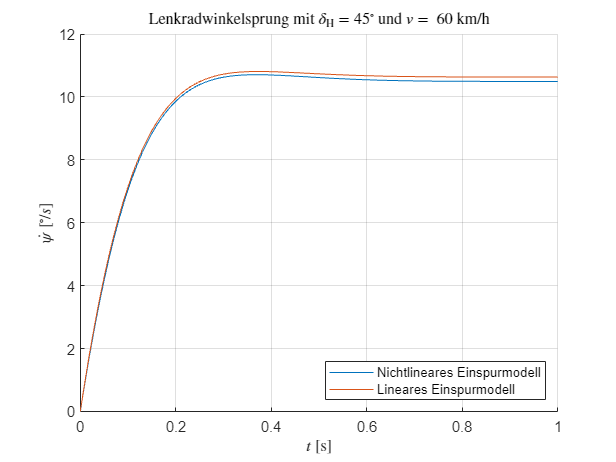

figure
hold on
plot(t,psip)
plot(t_out, y_out)
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\dot{\psi}$ $[^\circ/s]$','interpreter','latex')
title (['Lenkradwinkelsprung mit $\delta_{\rm H} = $' num2str(dH) '$^\circ$ und $v =$ ' num2str(v) ' km/h'] , 'Interpreter','latex'  )
legend('Nichtlineares Einspurmodell','Lineares Einspurmodell','Location','southeast')
grid
hold off

### 9.2.3 Seitenkräfte

Die Kreisfahrtests sollen zusätzlich zum gegebenen Einspurmodell auch mit einem neutral steuernden sowie einem übersteuernden Einspurmodell simuliert werden.

$C_v^*$ und $C_h^*$ wurden oben schon berechnet

#### Neutral steuerndes Einspurmodell

EG = 0 mit $C_{h,0 }= C_h$


$$C_{h,0} = F_{nh} * {C_h}^* = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g * 0} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v}} = F_{nh} * \frac{C_v}{F_{nv}}$$


Ch_0 = Fnh * (Cv/Fnv );

#### Übersteuerndes Einspurmodell

Es gilt $EG<0$. Für die Schräglaufsteifigkeit $C_{h,i}$ gilt damit mit $C_{h,i }= C_h$

$C_{h,i} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g *EG}$ und $C_{h,i} = B_h * F_{nh} * C * D$ mit $B_h \in [4...12]$

Es wird folgendes berechnet:

Zuerst Gleichung (2) in Gleichung (1) einsetzen: 


$$$B_h * F{nh} * C * D = F{nh} * \frac{1}{\frac{F{nv}}{Cv} - g EG}$$$


Da $$F_{nh}$ $auf beiden Seiten der Gleichung erscheint, kann man diese streichen, solange sie nicht null ist. Dadurch erhalten wir:


$$$B_h *C * D = \frac{1}{\frac{F{nv}}{Cv} - g EG}$$$


Um $$EG$$ zu isolieren, invertieren wir beide Seiten der Gleichung:


$$$\frac{1}{B_h * C * D} = \frac{F{nv}}{Cv} - g EG$$$


Nun können wir EG auf der rechten Seite isolieren, indem wir $$\frac{F{nv}}{Cv}$ $auf beiden Seiten der Gleichung subtrahieren:


$$$\frac{1}{B_h * C * D} - \frac{F{nv}}{Cv} = - g EG$$$


Da die rechte Seite der Gleichung negativ ist, multiplizieren wir beide Seiten der Gleichung mit -1, um EG positiv zu machen:


$$$\frac{F_{nv}}{Cv} - \frac{1}{B_h * C * D} = g EG$$$


Schließlich teilen wir beide Seiten der Gleichung durch $$g$$ um EG zu isolieren:


$$$EG = \frac{\frac{F_{nv}}{Cv} - \frac{1}{B_h* C * D}}{g}$$$


Da EG möglichst weit im Negativ liegen soll und $B_h \in [4...12]$ gilt, wird $B_h = 4$ gesetzt:

EG_klein = ((Fnv / Cv) - 1 / (4 * C * D)) / g;

Damit kann man $C_{h,i}$ berechnen: 

Ch_klein = Fnh * (1 / (Fnv / Cv - g * EG_klein));

#### Darstellung der Seitenkräfte

Die Seitenkräfte werden in einem Diagramm dargestellt. Hierfür wird die Pacejka-Magic-Formula: $$F_s = F_nD \sin(C\arctan(B\alpha - E(B\alpha - \arctan(B\alpha))))$
$

1. Erzeuge 100 gleichmäßig verteilte Werte zwischen 0 un 20 

alpha = linspace(0,20,200);

2. Konvertieren in Bogenmaß

alpha_bogenmass = alpha * pi / 180;

3. Verwenden der Pacejka-Funktion des Simulink Modells *Lenkradwinkelsprung *mithilfe des Skripts *Pacejka.m*

Fs_v = Pacejka(alpha_bogenmass, Fnv, Cv, C, D, E);
Fs_h = Pacejka(alpha_bogenmass, Fnh, Ch, C, D, E);
Fs_h_0 = Pacejka(alpha_bogenmass, Fnh, Ch_0, C, D, E);
Fs_h_i = Pacejka(alpha_bogenmass, Fnh, Ch_klein, C, D, E);

4. Visualisieren der Seitenkräfte über den Schräglaufwinkel

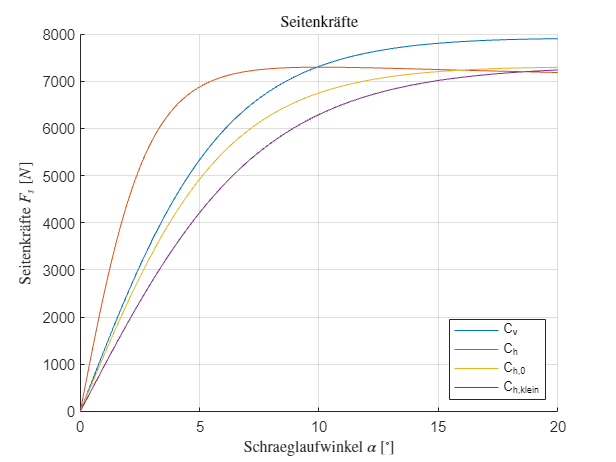

figure
hold on
plot(alpha, Fs_v, "DisplayName", "C_v")
plot(alpha, Fs_h, "DisplayName", "C_h")
plot(alpha, Fs_h_0, "DisplayName", "C_{h,0}")
plot(alpha, Fs_h_i, "DisplayName", "C_{h,klein}")
xlabel('Schraeglaufwinkel $\alpha$ $[^\circ]$', 'Interpreter', 'latex')
ylabel('Seitenkr\"afte $F_s$ $[N]$', 'Interpreter', 'latex')
title('Seitenkr\"afte', 'Interpreter', 'latex')
legend('show', 'Location', 'southeast')
grid
hold off

### 9.2.4 Gesteuerte stationäre Kreisfahrt

Simulation des Manövers *Kreisfahrtest mit konstanter Geschwindigkeit  *mit  $v=60 km/h $ und $\dot\delta_H = 1\frac{\degree }{s}$

Das setzen der Parameter ist in die Funktion *gesteuerte_kreisfahrt.m* ausgelagert. 

Darin wird für alle drei Fälle die folgende Formel verwendet:


$$\delta_{H,lin} = a_y * (\frac{l}{v^2} + EG) * i_S * \frac{180^\circ}{\pi}$$


Umrechnen der Geschwindigkeit in $\frac ms$

v = 60 / 3.6;

#### *Modell 1: EG = 0*

Schräglauftsteifigkeit $C_{h,0}$ aus *Neutral steuerndes Einspurmodell *setzen, sowie die anderen Parameter und $EG = 0$

EG_0 = 0;
figure
gesteuerte_kreisfahrt(EG_0, Cv, Ch_0, Fnv, Fnh, L, iS, '#FF0000');

#### *Modell 2: EG < 0*

Schräglauftsteifigkeit $C_{h,4}$ aus *Übersteuerndes Einspurmodell *setzen, sowie die anderen Parameter und $EG < 0$

 gesteuerte_kreisfahrt(EG_klein, Cv, Ch_klein, Fnv, Fnh, L, iS, '#0000FF');

#### Modell 3: EG

Schräglauftsteifigkeit und Eigenlenkgradient setzen:  

EG = (1 / g) * ((1 / Cv_stern) - (1 / Ch_stern));
Ch_EG = Fnh * (1 / (Fnv / Cv - g * EG));
gesteuerte_kreisfahrt(EG, Cv, Ch_EG, Fnv, Fnh, L, iS, '#00FF00');

Simulation des Simulink Modells  mit Simulation des linearen Einspurmodells 

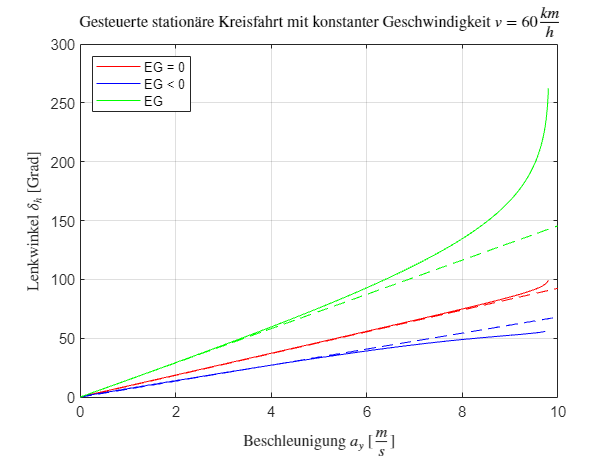

grid on
title('Gesteuerte station\"are Kreisfahrt mit konstanter Geschwindigkeit $v=60 \frac{km}{h}$', "Interpreter", "latex");
xlabel("Beschleunigung $a_y$ [$\frac{m}{s}$]", "Interpreter", "latex");
ylabel("Lenkwinkel $\delta_h$ [Grad]", "Interpreter", "latex");
legend("EG = 0", "", "EG < 0", "", "EG", "", "Location", "northwest");
hold off

### 9.2.5 Geregelte stationäre Kreisfahrt 

Simulation des Manövers Kreisfahrtest auf konstantem Radius mit stufenweise erhöhter Fahrgeschwindigkeit auf einem Soll-Radius von $R = 42.5m$. 

#### Regler parametrieren

Für den Regler wird die Übertragungsfunktion aus Kapitel 9.2.1 verwendet: 


$$G(s) = \frac{\dot{\psi}(s)}{\delta(s)} = K \cdot \frac{1 + T_zs}{s^2+2\sigma s + \omega_0^2}$$


diese kann mit dem "Tune PID Controller" verwendet werden.

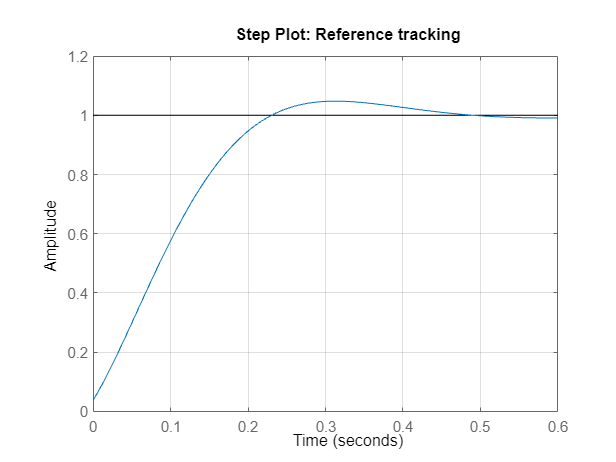

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(tf_gs,'PID',10);

% Get desired loop response
Response = getPIDLoopResponse(C2,tf_gs,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

         RiseTime: 0.1677
    TransientTime: 0.4213
     SettlingTime: 0.4190
      SettlingMin: 0.9099
      SettlingMax: 1.0479
        Overshoot: 4.7878
       Undershoot: 0
             Peak: 1.0479
         PeakTime: 0.3113




% Clear Temporary Variables
clear Response


Mit einer Phasenspanne von 60 Grad ist das System stabil, hat ein angemessenes Überschwingen in der Sprungantwort und eine moderate Bandbreite.

Die Anfordeungen, dass Overshoot= 0 und SettlingMax= 1 ist, sind erfüllt.

opts = pidtuneOptions('DesignFocus','reference-tracking','PhaseMargin',60);

[C2,pidInfo] = pidtune(tf_gs, 'PI', 10, opts);
clear opts

### Simulink-Modell

Regeln der Soll-Giergeschwindigkeit $\dot\psi$ mit $\delta_H$als Ausgangsgröße mit $v = \sqrt{a_y*R$ und $\dot\psi_{soll}=\frac {a_y} v$. Das setzen der Parameter ist in die Funktion* geregelte_kreisfahrt.m* ausgelagert. 

Für das  lineare Einspurmodell  gilt in diesem Fall:


$$\delta_{H,lin} = (\frac{l}{R} + EG*a_y) * i_S * \frac{180^\circ}{\pi}$$


Die Parameter EG und Ch werden gleich wie bei der gesteuerten Kreisfahrt gesetzt:

R = 42.5;
figure
geregelte_kreisfahrt(EG_0, Cv, Ch_0, Fnv, Fnh, C2.Kp, C2.Ki, L, iS, '#FF0000')
geregelte_kreisfahrt(EG_klein, Cv, Ch_klein, Fnv, Fnh, C2.Kp, C2.Ki, L, iS, '#0000FF')
geregelte_kreisfahrt(EG, Cv, Ch, Fnv, Fnh, C2.Kp, C2.Ki, L, iS, '#00FF00')

Visualisieren der drei Varianten der geregelten Kreisfahrt:

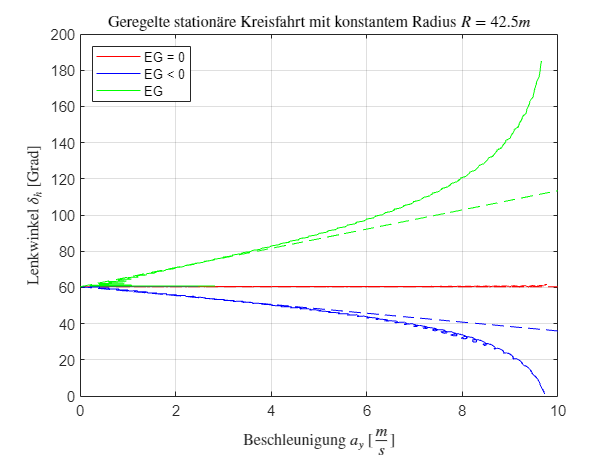

grid
title('Geregelte station\"are Kreisfahrt mit konstantem Radius $R=42.5m$', "Interpreter", "latex");
xlabel("Beschleunigung $a_y$ [$\frac{m}{s}$]", "Interpreter", "latex");
ylabel("Lenkwinkel $\delta_h$ [Grad]", "Interpreter", "latex");
legend("EG = 0", "", "EG < 0", "", "EG", "", "Location", "northwest");
%test
hold off